apple=1;

global data
data = csvread('Documents/prelim/global.1751_2014.csv');
data = data(:,[1,2]); % we need only the times and the CO2 emissions
data(:,2) = data(:,2)./1000;



C_at0  = 0;%590;
C_oc0  = 0;%1.4.* 10^5; % initial CO2 in ocean reservoir
C_veg0 = 0;%540;
C_so0  = 0;%1500;
T0     = 288.15; % kelvin

initial_conditions = [C_at0; C_oc0; C_veg0; C_so0; T0];% epsilon_T];
%epsilon_T = 1;
tspan = 1900:1:1910;
[t, y_] = ode45(@syst_odes, tspan, initial_conditions ) 

pCO2a = 
     0

resp_soil
     0

C_oc0
      140000

     0

pCO2a = 
   1.8873e-11

resp_soil
     0

C_oc0
      140000

   1.8086e-07

pCO2a = 
   2.8310e-11

resp_soil
     0

C_oc0
      140000

   2.7128e-07

pCO2a = 
   7.5493e-11

resp_soil
     0

C_oc0
      140000

   7.2343e-07

pCO2a = 
   8.3881e-11

resp_soil
     0

C_oc0
      140000

   8.0381e-07

pCO2a = 
   9.4366e-11

resp_soil
     0

C_oc0
      140000

   9.0428e-07

pCO2a = 
   9.4366e-11

resp_soil
     0

C_oc0
      140000

   9.0428e-07

pCO2a = 
   1.8873e-10

resp_soil
     0

C_oc0
      140000

   1.8086e-06

pCO2a = 
   2.3592e-10

resp_soil
     0

C_oc0
      140000

   2.2607e-06

pCO2a = 
   4.7184e-10

resp_soil
     0

C_oc0
      140000

   4.5215e-06

pCO2a = 
   5.1378e-10

resp_soil
     0

C_oc0
      140000

   4.9234e-06

pCO2a = 
   5.6621e-10

resp_soil
     0

C_oc0
      140000

   5.4259e-06

pCO2a = 
   5.6621e-10

resp_soil
     0

C_oc0
      140000

   5.4259e-06

pCO2a = 
   1

t =         1900
        1901
        1902
        1903
        1904
        1905
        1906
        1907
        1908
        1909


y_ =          0         0         0         0  288.1500
    0.5418    0.0012         0         0  288.1500
    1.0972    0.0049         0         0  288.1500
    1.6822    0.0111         0         0  288.1500
    2.2940    0.0201         0         0  288.1500
    2.9256    0.0318         0         0  288.1500
    3.5960    0.0465         0         0  288.1500
    4.3234    0.0643         0         0  288.1500
    5.0699    0.0854         0         0  288.1500
    5.8126    0.1099         0         0  288.1500


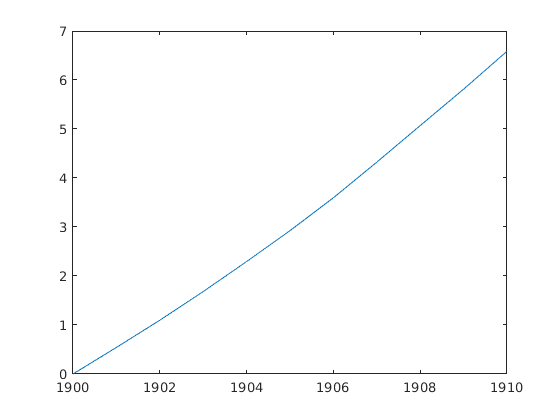

plot(t, y_(:,1))

function yprime = syst_odes(t, x_vec)%x, C_at, C_oc, C_veg, C_so, T, epsilon_t)
    
    C_at  = x_vec(1);
    C_oc  = x_vec(2);
    C_veg = x_vec(3);
    C_so  = x_vec(4);
    T     = x_vec(5);
    %epsilon_T = x_vec(7);
    
    %%% Initial conditions:
    C_at0  = 0;%590.0;%590;%[590, 596, 602];
    C_oc0  = 1.4.*10^(5);%[1.4,1.5,1.6] .* 10^5; % initial CO2 in ocean reservoir
    C_veg0 = 540;%[540, 550, 560];
    C_so0  = 1480;%[1480, 1500, 1520];
    T_0     = 288.15;%[288, 288.15, 288.3]; % kelvin    
    
    %%% Photosynthesis params:
    k_p  = 0.175;
    k_MM = 1.478;
    k_c  = 26.* 10^(-6);
    K_M  = 108.* 10^(-6);
    
    k_a = 1.773*10^20; % mole vol. of atmos
    
    %%% Plant resp. params:
    k_r = 0.0828;
    k_A = 8.7039*10^9;
    E_a = 54.63;
    
    %%% Soil resp. params:
    k_sr = 0.0303; % soil resp. rate const.
    k_B  = 157.072;
    
    %%% Turnover params:
    k_t = 0.0828;
    
    % Heat cap of earth's surface:
    c = 4.22.* 10^23; % J/kelvin
    
    % Constants:
    a_E   = 5.101*10^14; %Earth's surface area
    sigma = 5.67*10^(-8);
    latent_heat = 43655; % inverse mol; latent heat
    R = 8.314; % molar gas const.; J/(mol* K)
    H = 0.5915; % Relaive humididty; calibrated
    A = 0.203; % surface albedo
    S = 1231; % solar flux
    
    tao_CH4 = 0.0208; % see: atmos_down_flux to resolve problem
    P_0  = 1.26.* 10^(11); % water vapor saturations const.
    F_0  = 2.25 .* 10^(-2); % ocean flux rate const.
    
    chi  = 0.2; % characteristic CO2 solubility
    zeta = 40; % evasion factor

    
    f_max = 4; % max of warming cost function f(T)
    omega = 1; % nonlinearity of warming cost function f(T)
    T_c   = 2.4; % critical temperature of f(T)
    t_p   = 10; % num. prev. yrs used for temp pred.
    t_f   = 0; % num. yrs ahead for temp. proj.
    s_    = 30; % half-saturation time for epsilon(t) from 2014
    eps_max = 4.2; % max change in epsilon(t) from 2014

    f_gtm = 8.3259 * 10^(13); % conversion factor gTC->C; pg. 1 of Thomas' SI
    %%%%%%%%%%%%%%
    %%% Functions to solve
    %%%%%%%%%%%%%%
    
    % Socio-dynamics model

    
    % Compute intemediates (resp. and photosynthesis)
    pCO2a = mixingCO2a(C_at, C_at0, f_gtm, k_a);
    disp('pCO2a = ')
    disp(pCO2a)
    
    P     = photosynthesis(C_at, T, pCO2a, k_p, C_veg0, k_a, k_MM, k_c, K_M, T_0); 
    R_veg = plant_respiration(C_veg, T, k_r, k_A, E_a, T_0);
    R_so  = soil_respiration(T, C_so, k_sr, k_B, T_0);
    L_    = turnover(C_veg, k_t);
    F_oc  = ocean_flux(C_at, C_oc, F_0, chi, zeta, C_at0, C_oc0);
    F_d   = atmos_down_flux(pCO2a, A, S, P_0, latent_heat, T, tao_CH4, T_0);

    epsilon_T = baseline_CO2_emis(t, eps_max, s_);
    % Carbon uptake DEs
    x=0;
    
    y2 = C_at_dot(t, x, P, R_veg, R_so, F_oc, epsilon_T);  % Atmospheric
    y3 = C_oc_dot(t, F_oc);  % Ocean
    y4 = C_veg_dot(t, P, R_veg, L_); % Vegetation
    y5 = C_so_dot(t, R_so, L_);  % Soil

    % Temperature change
    y6 = c_T_dot(t, F_d, T, c, T_0);
    disp(F_oc)
    yprime = [y2(1); y3(1); y4(1); y5(1); y6(1)];
end


function interp_ = interp_co2_2014(t, ftimes, f)
    interp_ = interp1(ftimes, f, t); % interpolates dataset (ftimes, f) to time t
end


function C_at_dot_ = C_at_dot(t, x, P, R_veg, R_so, F_oc, epsilon)
    % Time rate of change for C_at
    %{
    Variables:
        x     = number of mitigators
        P     = carbon uptake from photosynthesis 
        R_veg = Resp. from vegetation
        R_so  = Resp. from soil
        F_oc  = Flux of CO2 from atmos. to ocean
    %}
    C_at_dot_ = epsilon.* (1)-P + R_veg + R_so - F_oc;
end


function C_oc_dot_ = C_oc_dot(t, F_oc)
    % Time rate of change for C_oc
    %{
    Variables:
        F_oc  = Flux of CO2 from atmos. to ocean
    %}
    C_oc_dot_ = F_oc;
end


function C_veg_dot_ = C_veg_dot(t, P, R_veg, L)
    % Time rate of change for C_veg
    %{
    Variables:
        P     = carbon uptake from photosynthesis
        R_veg = Resp. from vegetation
        L = turnover
    %}
    C_veg_dot_ = P - R_veg - L;
end


function C_so_dot_ = C_so_dot(t, R_so, L)
    % Time rate of change for C_so
    %{
    Variables:
        R_so = Resp. from soil
        L = turnover
    %}
    C_so_dot_ = L - R_so;
end


function c_T_dot_ = c_T_dot(t, F_d, T, c, T_0)
    % Time rate of change for average temp. multiplied by c
    %{
    Variables:
        F_d = net downward flux of radiation as defined in a function below
              (atmos_down_flux)
        T   = Average temp. 
    Parameters:
        sigma = Stefan-Boltzmann const.
        a_E   = Earth's surface area
    %}
    sigma = 5.67.*10^(-8);
    a_E   = 5.101.*10^(14);
    c_T_dot_ = (F_d - sigma*(T-T_0).^4).*a_E.*(1./c);
end


function emissions__ = baseline_CO2_emis(t, epsilon_max, s)
    % Computes baseline CO2 emissions in absence of mitigation
    %{
    
    %}
    global data
    if t<=2014
        emissions__ = interp_co2_2014(t, data(:,1), data(:,2));
    else
        emissions__ = data(end,2) + ((t-2014)*epsilon_max)/(t - 2014 + s);
    end
end





function photo = photosynthesis(C_at, T, pCO2a, k_p, C_veg0, k_a, k_MM, k_c, K_M, T_0)
    % Implement photosynthesis model
    %{
    Carbon uptake from the atmosphere via photosynthesis
    
    Variables:
        C_at = carbon uptake from the atmosphere
        T    = Temperature term
        pCO2a = mixing ratio of CO2 in the atmosphere
    params: array of parameters
        k_p  = photosynthesis rate constant
        k_a  = tot. molecules in the atmosphere
        k_MM = photosynthesis normalizing constant
        k_c  = photosynthesis compensation point
        K_M  = Michaelis-Menton rate constant; half-saturation point for
        photosynthesis
    %}
    cond1 = (pCO2a >= k_c);
    cond2 = ((T-T_0) >=-15 & (T-T_0)<= 25);
    if cond1 & cond2
        photo = k_p .* C_veg0 .* k_MM .* ( (pCO2a - k_c)./(K_M + pCO2a - k_c) ).*( (((15+(T-T_0)).^2) .*(25-(T-T_0)))./(5625) );
    else
        photo = 0;
    end
end


function mixing_ratio = mixingCO2a(C_at, C_at0, f_gtm, k_a)
    % Computes mixing ratio of CO2 in the atmosphere
    % i.e. pCO2a
    %{
    variables:
        C_at  = deviation of atmos. C02 (from pre-indus 1800)
        C_at0 = initial value for C_at
        f_gtm = converesion factor from gTC to moles of carbon
        k_a   = tot. mmolecules in the atmosphere
    %}
    f_gtm = 8.3259 .* 10^13;
    mixing_ratio = (f_gtm.*(C_at + C_at0))./(k_a);
end


function resp_plant = plant_respiration(C_veg, T, k_r, k_A, E_a, T_0)
    % Plant respiration model
    %{
    variables:
        C_veg = deviation in CO2 in vegetation
        k_r = plant respiration constant
        k_A = plant resp. normalization constant
        E_a = plant resp. activation energy
        R   = molar gas constant
        T_0 = initial average atmos. temp. 
    %}
    R = 8.314;
    
    resp_plant = k_r .* C_veg .* k_A .* exp( -(E_a)./(R.*(T)) );    
end


function resp_soil = soil_respiration(T, C_so, k_sr, k_B, T_0)
    % Soil respiration model
    %{
    variables:
        T    = deviation in temp.
        C_so = deviation in CO2 in soil
    parameters: 
        k_sr = soil resp. rate const.
        k_B  = soil resp. rate normalization const.
        T_0  = initial average atmos. temp.
    %}
    
    %disp('Temp in R_so = ')
    %disp(T)
    resp_soil = k_sr .* C_so .* k_B .* exp( -(308.56)./(T - 227.13) );
    disp('resp_soil')
    disp(resp_soil)
end


function living = turnover(C_veg, k_t)
    % Assume constant fraction of plants dying in a given unit of time
    %{
    variables:
        C_veg = deviation in CO2 in vegetation
    parameters:
        k_t = turnover rate constant; how fast/slow vegetation dies and
        comes back
    %}
    living = k_t .* C_veg;
end


function flux_ocean = ocean_flux(C_at, C_oc, F_0, chi, zeta, C_at0, C_oc0)
    %
    %{
    variables:
        C_at = deviation of atmos. CO2 (from pre-indus 1800)
        C_oc = deviation of CO2 in ocean
    parameters:
        F_0   = ocean flux rate const.
        chi   = characteristic CO2 solubility
        zeta  = "evasion factor"
        C_at0 = initial CO2 in atmos. 
        C_oc0 = initial value of C_oc
    %}
    disp('C_oc0')
    disp(C_oc0)
    flux_ocean = F_0 .* chi .* (C_at - zeta.*(C_at0./C_oc0).*C_oc);
end


function flux_down = atmos_down_flux(pCO2a, A, S, P_0, L, T, tao_CH4, T_0)
    % "Grey-atmosphere approx."; models atmospheric dynamics
    %{
    Computes net downward flux of radiation absorbed at the planet's
    surface
    
    variables:
        pCO2a = mixing ratio of CO2 in atmos. as above
    parameters:
        A   = surface albedo
        S   = incoming solar flux
        P_0 = water vapor saturation const.
        L   = latent heat per mole of water
        R   = molar gas const.
    Computed parameter:
        tao = vertical opacity of the greenhouse atmosphere
    %}
    H = 0.5915;
    R = 8.314;
    
    tao_CO2 = 1.73.*(pCO2a).^0.263;
    tao_H2O = 0.0126.*( H.*P_0.*exp(-(L./(R.*(T-T_0)))) ).^0.503;
    %tao_CH4 = 0.0231;
    tao_ = tao_CH4 + tao_CO2 + tao_H2O;
    
    flux_down = ( ((1-A).*S)./4 ).*(1+(3/4)).*tao_;
end


